## **Exercício 4**

**(a)**

**i.**

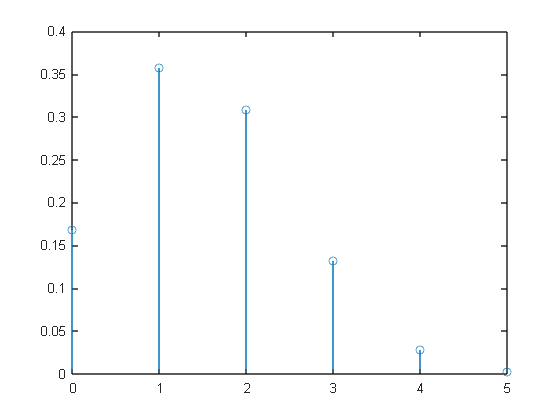

p = 0.3;    % 30% prob
N = 100000;
s = 0:5;    % Amostras vão de 0 a 5

for i = 1 : 6
    k = i - 1;
    pX(i) = fMassaProb(N,p,k,n);
end

stem(s,pX)

**ii.**

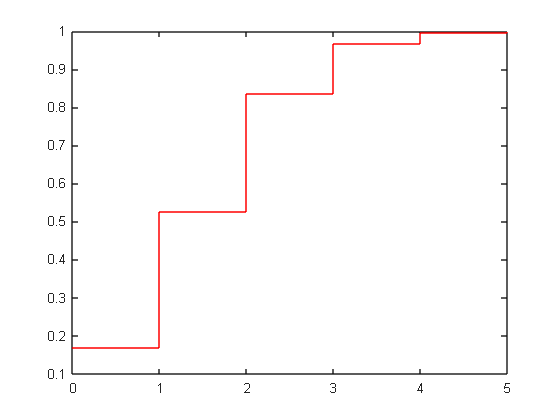

x = 0:5;    % Amostras
fd = cumsum(pX);

stairs([0 1 2 3 4 5],fd,'r');

pX(1) + pX(2) + pX(3)

ans = 0.8352

**(b)**

**i.**

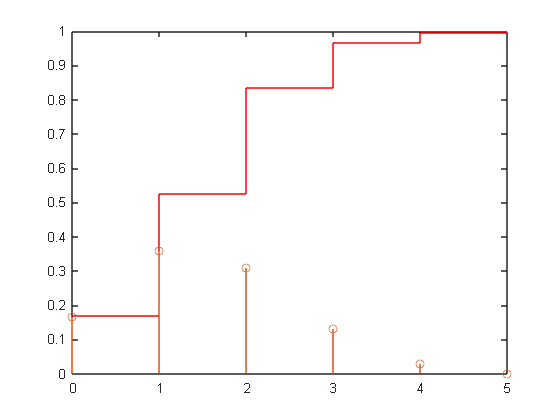

pX = zeros(1,6);
n = 5;      % Número de peças escolhidas
p = 3/10;

for i = 1:5
    k = i - 1;
    pX(i) = factorial(n) / (factorial(k) * factorial(n-k)) * p^k * (1-p)^(n-k);
end

figure(1);
hold on;

x = 0:5;
stem(x,pX);

**ii.**

p = pX(1) + pX(2) + pX(3)

p = 0.8369